L5 Primera Part                                                                                                            Marta Granero i Martí

Exercici 2

L’objectiu d’aquesta pràctica és de separar les vocals de les consonants d’un missatge encriptat. 

Suposeu que d’un missatge eliminem els espais en blanc i els signes de puntuació i seguidament el reescrivim substituint cada lletra per l’anterior segons l’ordenació alfabètica; és a dir, la frase 

**SETZE JUTGES MENGEN FETGE D’UN PENJAT **

**                                                  RDSYDITSFDRLDMFDMEDSFDCTMODMIZS**

Escriviu un programa que processi un text i formi una matriu quadrada de dimensió 26, de tal manera que el valor de l’element (𝑖,𝑗) **sigui el nombre de vegades que la parella formada per la lletra 𝑖 i la lletra 𝑗 apareix en el text encriptat.** Aquesta matriu s’anomena **matriu de freqüència de dígrafs**. 

Seguidament, calculeu la descomposició en valors singulars de la matriu i escolliu les columnes 𝑈 i 𝑉 corresponents al valor singular de major mòdul. Les components d’aquests vectors són totes del mateix signe i són proporcionals a les freqüències de cada lletra; per tant, segons la llengua hi haurà unes freqüències més o menys típiques per a cada lletra. 

Considereu a continuació les columnes de 𝑈 i 𝑉 corresponents al segon valor singular més gran en mòdul. Totes les seves components són de l’interval [−1,1]  i , si dibuixem en el pla els punts determinats per les parelles (𝑢𝑖,𝑣𝑖), obtenim 26 punts a l’interior del quadrat de costat 2 i centrat a l’origen. `La major part d’aquests punts estan en el segon i quart quadrant i les vocals en l’altre. Això és degut a la freqüència més gran de parelles del tipus vocal-consonant i consonant-vocal que no de les del tipus consonant-consonant o vocal-vocal. `

Naturalment, hi ha excepcions ja que, segons la llengua, podem tenir, per exemple, una freqüècia elevada d'algunes parelles de consonants.

Agafeu un text una mica llarg, encripteu-lo i apliqueu-hi el que s'ha comentat anteriorment. 

**Joc de proves. **Feu-ho, també, per a idiomes altres que el català i/o castellà. Presenteu un mínim de 3 idiomes diferents i textos de més de 1500 paraules.

**Conclusions.** Comenteu i argumenteu els resultats que s'obtenen. 

%Carreguem les dades d'un fitxer i les llegim
textinput = importdata("textEntradaEn.txt");
%Netegem el text dels signes de puntuació
newText = erasePunctuation(textinput);
%Netegem el text dels espais
newText = erase(newText," ")

newText = 1×1 cell array
    {'OnemorningwhenGregorSamsawokefromtroubleddreamshefoundhimselftransformedinhisbedintoahorribleverminHelayonhisarmourlikebackandifheliftedhisheadalittlehecouldseehisbrownbellyslightlydomedanddividedbyarchesintostiffsectionsThebeddingwashardlyabletocoveritandseemedreadytoslideoffanymomentHismanylegspitifullythincomparedwiththesizeoftherestofhimwavedabouthelplesslyashelookedWhatshappenedtomehethoughtItwasntadreamHisroomaproperhumanroomalthoughalittletoosmalllaypeacefullybetweenitsfourfamiliarwallsAcollectionoftextilesampleslayspreadoutonthetableSamsawasatravellingsalesmanandaboveittherehungapicturethathehadrecentlycutoutofanillustratedmagazineandhousedinanicegildedframeItshowedaladyfittedoutwithafurhatandfurboawhosatuprightraisingaheavyfurmuffthatcoveredthewholeofherlowerarmtowardstheviewerGregorthenturnedtolookoutthewindowatthedullweatherDropsofraincouldbeheardhittingthepanewhichmadehimfeelquitesadHowaboutifIsleepalittlebitlongerandforgetallthisnonsensehetho

%Convertim a majúscules, restem 1 lletra, i després la convertim en enter,
%i com que és cíclic l'abecedari, fem mod 26(mòdul #lletres)
newText = mod((upper(char(newText)) - 'A'-1),26)+1

newText =     14    13     4    12    14    17    13     8    13     6    22     7     4    13     6    17     4     6    14    17    18    26    12    18    26    22    14    10     4     5    17    14    12    19    17    14    20     1    11     4     3     3    17     4    26    12    18     7     4     5


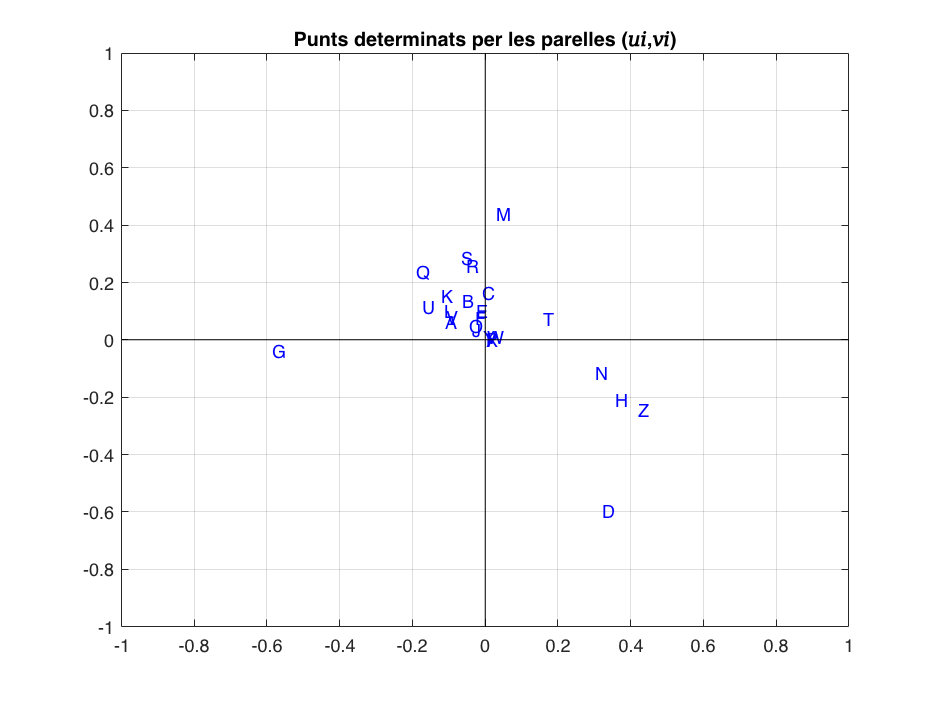


% Degut a la naturalesa del problema, tindrem una matriu on la majoria
% de parelles d'elements, (i,j) serà 0, per tant farem servir una matriu
% dispersa. És una matriu que té una mida molt gran i la majoria dels
% elements són 0. Per tant generarem la matriu: 

%Els elements corresponents a i i j especifiquen parells de subíndex
% matriuDígrafs(i,j), que determinen la col·locació dels valors de v a la sortida.
i = newText;
j = newText([2:length(newText) 1]);
v = 1;
%Matriu que tindrà mida 26x26 i la convertim a emmagatzematge complet.
matriuDigrafs = full(sparse(i,j,v));
%Retornem un vector fila, de 26 posicions, que contindrà la suma de 
% cada lletra que hi ha per cada columna.
freq = sum(matriuDigrafs);

% Calculeu la descomposició en valors singulars de la matriu
[U,S,V] = svd(matriuDigrafs);
for i = 1:26
    %Plotegem les lletres
    text(U(i,2),V(i,2),char('A'+ i-1 ), "Color",'b')
end

%Dibuixem el gràfic
axis([-1 1 -1 1]);
grid on;
box;
title("Punts determinats per les parelles (𝑢𝑖,𝑣𝑖)");

line([0 0],[-1 1],'Color','black');
line([-1 1],[0 0],'Color','black');

xlim([-1.00 1.00]);
ylim([-1.00 1.00]);

clearvars
%Carreguem les dades d'un fitxer i les llegim
textinput = importdata("textEntradaEsp.txt");
%Netegem el text dels signes de puntuació
newText = erasePunctuation(textinput);
%Netegem el text dels espais
newText = erase(newText," ")

newText = 1×1 cell array
    {'UnamañanatrasunsueñointranquiloGregorioSamsasedespertóconvertidoenunmonstruosoinsectoEstabaechadodeespaldassobreundurocaparazónyalalzarlacabezaviosuvientreconvexoyoscurosurcadoporcurvadascallosidadessobreelquecasinoseaguantabalacolchaqueestabaapuntodeescurrirsehastaelsueloNumerosaspataspenosamentedelgadasencomparaciónconelgrosornormaldesuspiernasseagitabansinconciertoQuémehaocurridoNoestabasoñandoSuhabitaciónunahabitaciónnormalaunquemuypequeñateníaelaspectohabitualSobrelamesahabíadesparramadounmuestrariodepañosSamsaeraviajantedecomercioydelaparedcolgabaunaestamparecientementerecortadadeunarevistailustradaypuestaenunmarcodoradoLaestampamostrabaaunamujertocadaconungorrodepielesenvueltaenunaestolatambiéndepielesyquemuyerguidaesgrimíaunampliomanguitoasimismodepielqueocultabatodosuantebrazoGregoriomiróhacialaventanaestabanubladoysobreelcincdelalféizarrepiqueteabanlasgotasdelluvialoquelehizosentirunagranmelancolíaBuenopensóysisiguiesedurmiendounratoymeolvidased

%Convertim els accents en espanyol
str = {'Á', 'É', 'Í', 'Ó', 'Ú', 'á', 'é', 'í', 'ó', 'ú'};
strreplace = {'A', 'E', 'I', 'O', 'U', 'a', 'e', 'i', 'o', 'u'};
for j = 1:length(newText)
    for i = 1:numel(str)
        newText{j} = regexprep(newText{j}, str{i}, strreplace{i});
    end
end
newText

newText = 1×1 cell array
    {'UnamañanatrasunsueñointranquiloGregorioSamsasedespertoconvertidoenunmonstruosoinsectoEstabaechadodeespaldassobreundurocaparazonyalalzarlacabezaviosuvientreconvexoyoscurosurcadoporcurvadascallosidadessobreelquecasinoseaguantabalacolchaqueestabaapuntodeescurrirsehastaelsueloNumerosaspataspenosamentedelgadasencomparacionconelgrosornormaldesuspiernasseagitabansinconciertoQuemehaocurridoNoestabasoñandoSuhabitacionunahabitacionnormalaunquemuypequeñateniaelaspectohabitualSobrelamesahabiadesparramadounmuestrariodepañosSamsaeraviajantedecomercioydelaparedcolgabaunaestamparecientementerecortadadeunarevistailustradaypuestaenunmarcodoradoLaestampamostrabaaunamujertocadaconungorrodepielesenvueltaenunaestolatambiendepielesyquemuyerguidaesgrimiaunampliomanguitoasimismodepielqueocultabatodosuantebrazoGregoriomirohacialaventanaestabanubladoysobreelcincdelalfeizarrepiqueteabanlasgotasdelluvialoquelehizosentirunagranmelancoliaBuenopensoysisiguiesedurmiendounratoymeolvidased

%Convertim a majúscules, restem 1 lletra, i després la convertim en enter,
%i com que és cíclic l'abecedari, fem mod 26(mòdul #lletres)
newText = mod((upper(char(newText)) - 'A'-1),26)+1

newText =     20    13    26    12    26    14    26    13    26    19    17    26    18    20    13    18    20     4    14    14     8    13    19    17    26    13    16    20     8    11    14     6    17     4     6    14    17     8    14    18    26    12    18    26    18     4     3     4    18    15


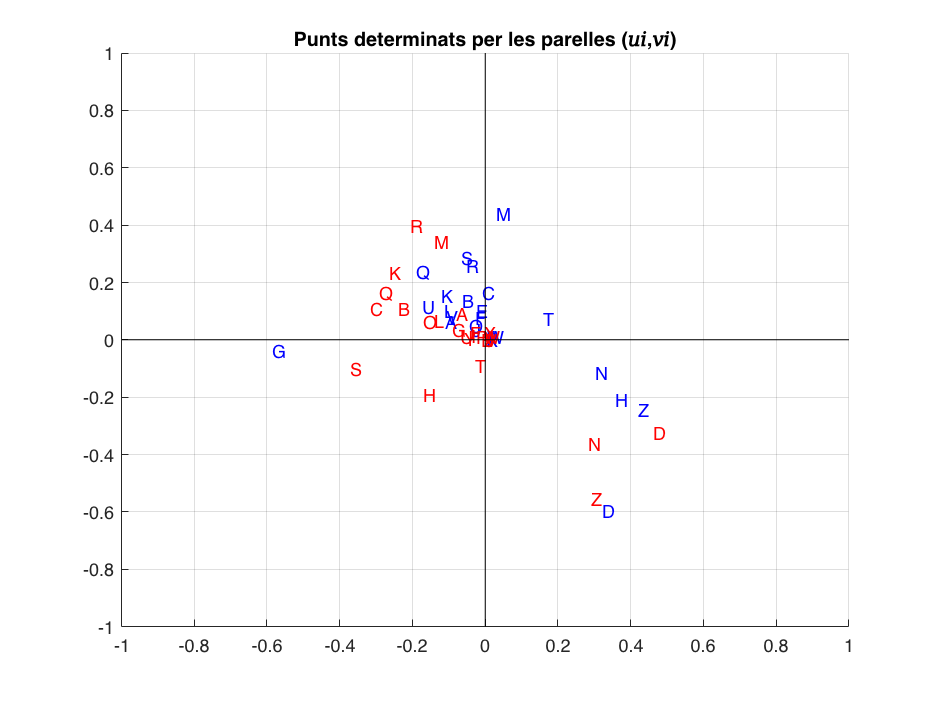

%Els elements corresponents a i i j especifiquen parells de subíndex
% matriuDígrafs(i,j), que determinen la col·locació dels valors de v a la sortida.
i = newText;
j = newText([2:length(newText),1]);
v = 1;
matriuDigrafs = full(sparse(i,j,v));
%Matriu que tindrà mida 26x26 i la convertim a emmagatzematge complet.
%Retornem un vector fila, de 26 posicions, que contindrà la suma de cada lletra que hi ha per cada columna.
freq = sum(matriuDigrafs);

% Calculeu la descomposició en valors singulars de la matriu
[U,S,V] = svd(matriuDigrafs);
for i = 1:26
    text(U(i,2),V(i,2),char('A'+ i-1 ), "Color",'r')
end

axis([-1 1 -1 1]);
box;
title("Punts determinats per les parelles (𝑢𝑖,𝑣𝑖)");

line([0 0],[-1 1],'Color','black');
line([-1 1],[0 0],'Color','black');

xlim([-1.00 1.00]);
ylim([-1.00 1.00]);
grid on;

clearvars
%Carreguem les dades d'un fitxer i les llegim
textinput = importdata("textEntradaCa.txt");
%Netegem el text dels signes de puntuació
newText = erasePunctuation(textinput);
%Netegem el text dels espais
newText = erase(newText," ")

newText = 1×1 cell array
    {'UnmatídesprésdunsomniintranquilGregorioSamsaesvadespertarconvertitenunmonstruósinsecteEstavatiratdesquenasobreunaduracloscaienalçarelcapvaveureelseuventreconvexifoscsolcatpercorbadescallositatssobreelqualgairebénosaguantavaelcobertorqueestavaapuntdescórrersefinsalsòlNombrosespotespenosamentprimesencomparacióambelgruixnormaldelessevescamessagitavensenseconcertQuèmhaocorregutNoestavasomiantLasevahabitacióunahabitaciónormalencaraquemoltpetitatenialaspectehabitualSobrelataulahaviaescampatunmostraridedrapsSamsaeraviatjantdecomerçidelaparetpenjavaunaestamparecentmentretalladadunarevistaillustradaiposadaenunmarcdauratLestampamostravaaunadonatocadaambuncapelldepellsembolicadaenunaestolatambédepellsiquemoltalçadaesgrimiaunamplimaniguetaixímateixdepellqueocultavatotelseuavantbraçGregoriovamirarcapalafinestraestavaennuvolatisobreelzincdelampittritllejavenlesgotesdeplujalaqualcosalivafersentirunagranmelancoliaBovapensarisicontinuésdormintunaestonaimoblidésdetotesaque

%Traiem accents en català(tancats)
str = {'É', 'Í', 'Ó', 'Ú', 'é', 'í', 'ó', 'ú'};
strreplace = {'E', 'I', 'O', 'U', 'e', 'i', 'o', 'u'};
for j = 1:length(newText)
    for i = 1:numel(str)
        newText{j} = regexprep(newText{j}, str{i}, strreplace{i});
    end
end
%Traiem accents en català(oberts)
str = {'À', 'È', 'Ò', 'à', 'è', 'ó'};
strreplace = {'A', 'E', 'O', 'a', 'e', 'o'};
for j = 1:length(newText)
    for i = 1:numel(str)
        newText{j} = regexprep(newText{j}, str{i}, strreplace{i});
    end
end
newText

newText = 1×1 cell array
    {'UnmatidespresdunsomniintranquilGregorioSamsaesvadespertarconvertitenunmonstruosinsecteEstavatiratdesquenasobreunaduracloscaienalçarelcapvaveureelseuventreconvexifoscsolcatpercorbadescallositatssobreelqualgairebenosaguantavaelcobertorqueestavaapuntdescorrersefinsalsòlNombrosespotespenosamentprimesencomparacioambelgruixnormaldelessevescamessagitavensenseconcertQuemhaocorregutNoestavasomiantLasevahabitaciounahabitacionormalencaraquemoltpetitatenialaspectehabitualSobrelataulahaviaescampatunmostraridedrapsSamsaeraviatjantdecomerçidelaparetpenjavaunaestamparecentmentretalladadunarevistaillustradaiposadaenunmarcdauratLestampamostravaaunadonatocadaambuncapelldepellsembolicadaenunaestolatambedepellsiquemoltalçadaesgrimiaunamplimaniguetaiximateixdepellqueocultavatotelseuavantbraçGregoriovamirarcapalafinestraestavaennuvolatisobreelzincdelampittritllejavenlesgotesdeplujalaqualcosalivafersentirunagranmelancoliaBovapensarisicontinuesdormintunaestonaimoblidesdetotesaque

%Convertim a majúscules i després al valor enter del caràcter
newText = mod((upper(char(newText)) - 'A'-1),26)+1

newText =     20    13    12    26    19     8     3     4    18    15    17     4    18     3    20    13    18    14    12    13     8     8    13    19    17    26    13    16    20     8    11     6    17     4     6    14    17     8    14    18    26    12    18    26     4    18    21    26     3     4


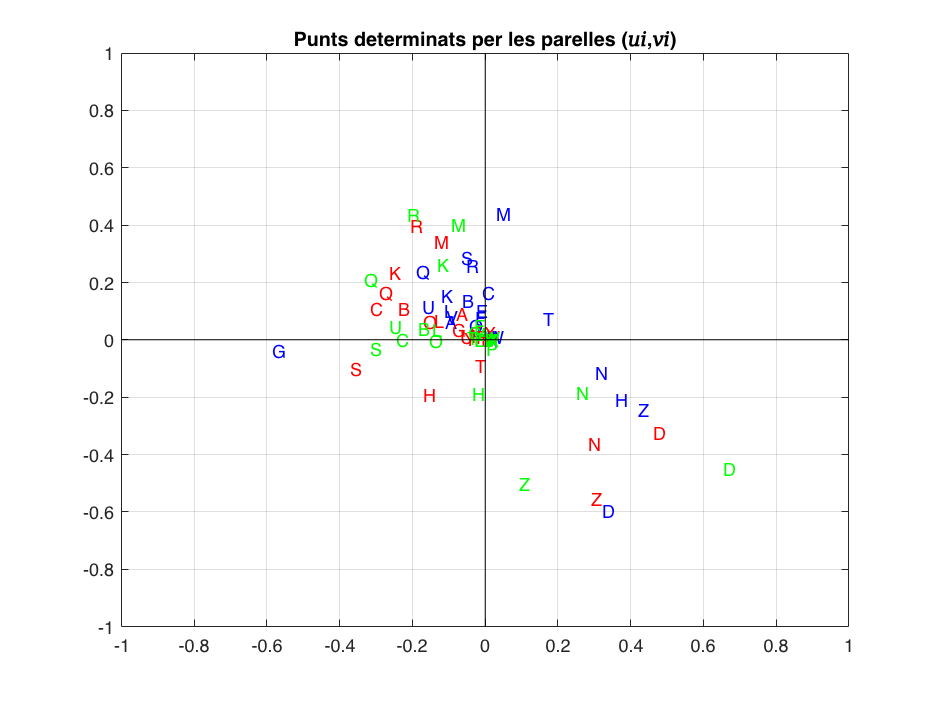

%Els elements corresponents a i i j especifiquen parells de subíndex
% matriuDígrafs(i,j), que determinen la col·locació dels valors de v a la sortida.
i = newText;
j = newText([2:length(newText),1]);
v = 1;
matriuDigrafs = full(sparse(i,j,v));
%Matriu que tindrà mida 26x26 i la convertim a emmagatzematge complet.
%Retornem un vector fila, de 26 posicions, que contindrà la suma de cada lletra que hi ha per cada columna.
freq = sum(matriuDigrafs);

% Calculeu la descomposició en valors singulars de la matriu
[U,S,V] = svd(matriuDigrafs);
for i = 1:26
    text(U(i,2),V(i,2),char('A'+ i-1 ), "Color",'green')
end

axis([-1 1 -1 1]);
box;
title("Punts determinats per les parelles (𝑢𝑖,𝑣𝑖)");

line([0 0],[-1 1],'Color','black');
line([-1 1],[0 0],'Color','black');

xlim([-1.00 1.00]);
ylim([-1.00 1.00]);
grid on;

clearvars
%Carreguem les dades d'un fitxer i les llegim
textinput = importdata("textEntradaIt.txt");
%Netegem el text dels signes de puntuació
newText = erasePunctuation(textinput);
%Netegem el text dels espais
newText = erase(newText," ")

newText = 1×1 cell array
    {'GregorioSamsasvegliandosiunamattinadasogniagitatisitrovòtrasformatonelsuolettoinunenormeinsettoimmondoRiposavasullaschienaduracomeunacorazzaesollevandounpocoilcapovedevailsuoventrearcuatobrunoedivisointantisegmentiricurviincimaacuilacopertadalettovicinaascivolargiùtuttasimantenevaafaticaLegambenumeroseesottilidafarpietàrispettoallasuacorporaturanormaletremolavanosenzatreguainunconfusoluccichiodinanziaisuoiocchiCosamèavvenutopensòNoneraunsognoLasuacameraunastanzettadigiusteproporzionisoltantounpopiccolasenestavatranquillafralequattrobennoteparetiSullatavolauncampionariodisfattoditessutiSamsaeracommessoviaggiatoreesopraappesoallapareteunritrattoritagliatodaluinoneramoltodaunarivistaillustrataemessodentrounabellacornicedorataraffiguravaunadonnasedutamabendrittasulbustoconunberrettoeunboadipellicciaessalevavaincontroachiguardavaunpesantemanicottoincuiscomparivatuttolavambraccioLosguardodiGregoriosirivolsealloraversolafinestraeilcielofoscosisentivanobattereleg

%Traiem accents en català(tancats)
str = {'É', 'é'};
strreplace = {'E', 'e'};
for j = 1:length(newText)
    for i = 1:numel(str)
        newText{j} = regexprep(newText{j}, str{i}, strreplace{i});
    end
end
%Traiem accents en català(oberts)
str = {'À', 'È', 'Ì', 'Ò', 'Ù', 'à', 'è', 'ì', 'ò', 'ù'};
strreplace = {'A', 'E', 'I','O', 'U', 'a', 'e', 'i', 'o', 'u'};
for j = 1:length(newText)
    for i = 1:numel(str)
        newText{j} = regexprep(newText{j}, str{i}, strreplace{i});
    end
end
newText

newText = 1×1 cell array
    {'GregorioSamsasvegliandosiunamattinadasogniagitatisitrovotrasformatonelsuolettoinunenormeinsettoimmondoRiposavasullaschienaduracomeunacorazzaesollevandounpocoilcapovedevailsuoventrearcuatobrunoedivisointantisegmentiricurviincimaacuilacopertadalettovicinaascivolargiututtasimantenevaafaticaLegambenumeroseesottilidafarpietarispettoallasuacorporaturanormaletremolavanosenzatreguainunconfusoluccichiodinanziaisuoiocchiCosameavvenutopensoNoneraunsognoLasuacameraunastanzettadigiusteproporzionisoltantounpopiccolasenestavatranquillafralequattrobennoteparetiSullatavolauncampionariodisfattoditessutiSamsaeracommessoviaggiatoreesopraappesoallapareteunritrattoritagliatodaluinoneramoltodaunarivistaillustrataemessodentrounabellacornicedorataraffiguravaunadonnasedutamabendrittasulbustoconunberrettoeunboadipellicciaessalevavaincontroachiguardavaunpesantemanicottoincuiscomparivatuttolavambraccioLosguardodiGregoriosirivolsealloraversolafinestraeilcielofoscosisentivanobattereleg

%Convertim a majúscules i després al valor enter del caràcter
newText = mod((upper(char(newText)) - 'A'-1),26)+1

newText =      6    17     4     6    14    17     8    14    18    26    12    18    26    18    21     4     6    11     8    26    13     3    14    18     8    20    13    26    12    26    19    19     8    13    26     3    26    18    14     6    13     8    26     6     8    19    26    19     8    18


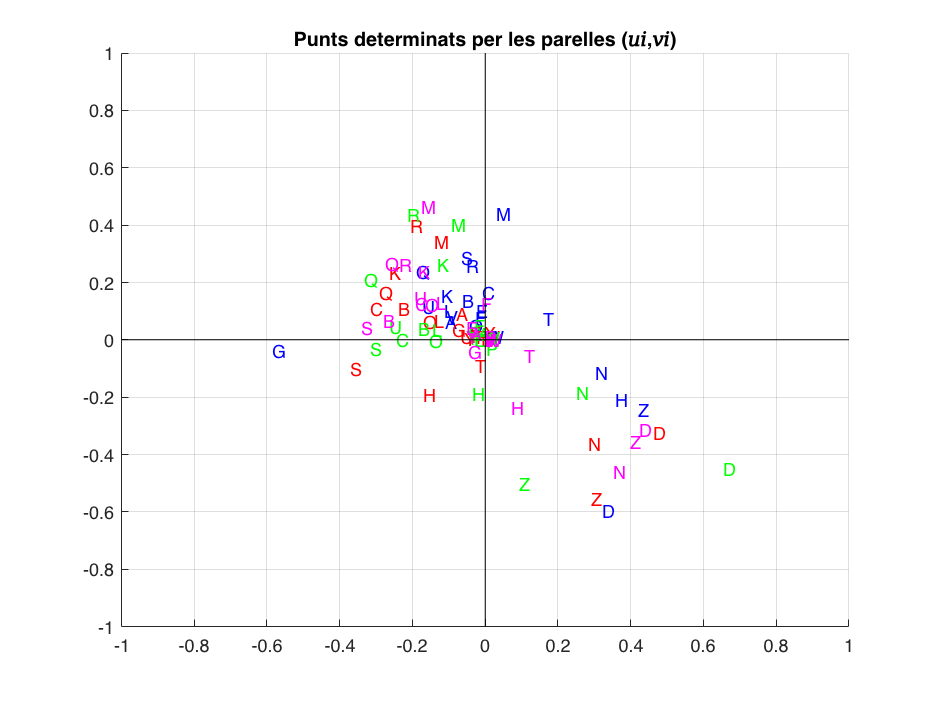

%Els elements corresponents a i i j especifiquen parells de subíndex
% matriuDígrafs(i,j), que determinen la col·locació dels valors de v a la sortida.
i = newText;
j = newText([2:length(newText),1]);
v = 1;
matriuDigrafs = full(sparse(i,j,v));
%Matriu que tindrà mida 26x26 i la convertim a emmagatzematge complet.
%Retornem un vector fila, de 26 posicions, que contindrà la suma de cada lletra que hi ha per cada columna.
freq = sum(matriuDigrafs);

% Calculeu la descomposició en valors singulars de la matriu
[U,S,V] = svd(matriuDigrafs);
for i = 1:26
    text(U(i,2),V(i,2),char('A'+ i-1 ), "Color",'magenta')
end

axis([-1 1 -1 1]);
box;
title("Punts determinats per les parelles (𝑢𝑖,𝑣𝑖)");

line([0 0],[-1 1],'Color','black');
line([-1 1],[0 0],'Color','black');

xlim([-1.00 1.00]);
ylim([-1.00 1.00]);
grid on;

CONCLUSIONS

Tal i com podem veure a les gràfiques que s'han obtingut després d'encriptar els missatges, podem veure que el que s'enunicava de bon primer a l'enunciat de la pràctica s'ha bonament complert. Com podem veure, pels 4 idiomes, tenim la majoria de punts en el segon i el quart quadrant.

Com podríem deduir, el conjunt de punts que hem dibuixat pel català(color verd) com pel castellà(color vermell) es mantenen tot i la variància lleu de l'ús de les vocals A i E. Tot i la variància de punts, notem que les construccions gramaticals del català i el castellà es mantenen en la majoria, i les parelles, consonants-vocals i vocals-consonants són en la major part, iguals.

De la mateixa forma, tampoc hi ha molta diferència entre el conjunt de llengües {català,el castellà} i l'italià(color magenta), degut al fet que són dues llengües romàniques, podem seguir veient que les construccions que es poden fer no varien massa.

Com podem veure, en el cas de l'anglès si que tenim una freqüència més elevada de consonants, com per exemple, podem observar que l'anglès té un nombre molt elevat de (R,T,N,S,L), que es traduirien en el nostre cas per (Q,S,M,R,K). En el cas de l'espanyol i el català, podem notar que es fan servir d'igual forma les construccions de vocals.

D'altra banda, l'italià on és la llengua on predominen més les construccions de vocals.